mutated=[3,6,9,10,14,15,18,21,28:30]; %+30
unmutated=[1,2,4,5,7,11,13,16,17,19,20,22:26];
nr=[8,27];

patients=[1:11,13:30];
inputFolder='/Figures/03_22/paramAnalysis/';
%inputFolder='/Figures/02_20_4_3c/';
sheet=1;
%inputFolder='/Figures/'

outputFolder='/Figures/03_22/paramAnalysis/';
inputTableAnalysis="regression.xlsx";
inputTableParams="paramsAll_extendedWithChars_sepWithChars";
alpha=0.05;

analysisResults=readtable(strcat(pwd,inputFolder,inputTableAnalysis));

params=readtable(strcat(pwd,inputFolder,inputTableParams));


sigRegs=[];
names=analysisResults.Properties.VariableNames;
for i=1:size(analysisResults,2)
    for j=1:size(analysisResults,2)
        if analysisResults(i,j).Variables<alpha
            nameI=string(names(i));
            nameJ=string(names(j));
            if nameI.replace("_logged","")~=nameJ.replace("_logged","")
                sigRegs=[sigRegs;[nameI,nameJ]];
            end
       
        end
    end
end


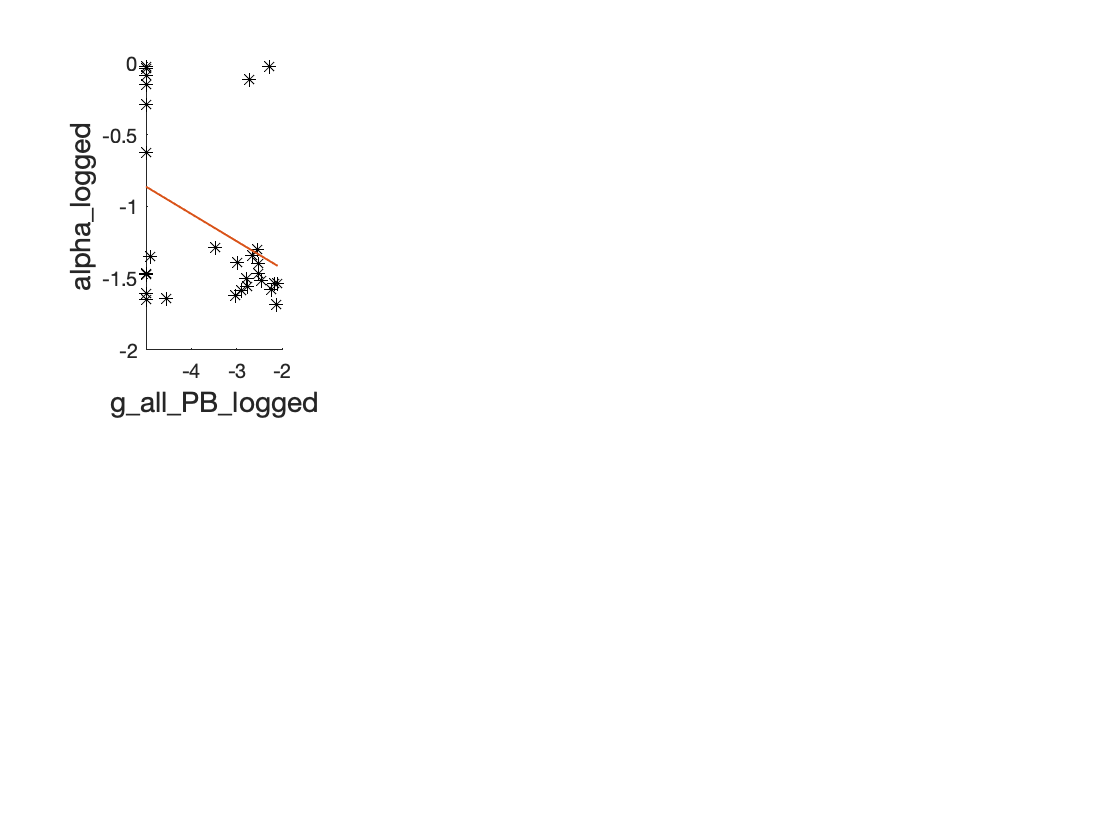

rows=176;
counter=0;
figure;
for row=rows
    counter=counter+1;
    subplot(2,5,counter)
    nameI=sigRegs(row,1);
    nameJ=sigRegs(row,2);
    if nameI.endsWith("_logged")
        dataI=log10(params(:,nameI.replace("_logged","")).Variables);
    else
        dataI=params(:,nameI).Variables;
    end
    if nameJ.endsWith("_logged")
        dataJ=log10(params(:,nameJ.replace("_logged","")).Variables);
    else
        dataJ=params(:,nameJ).Variables;
    end
    scatter(dataI,dataJ,'k*'); hold on;
    mdl=fitlm(dataI,dataJ);
    plot([min(dataI),max(dataI)],mdl.Coefficients.Estimate(1)+mdl.Coefficients.Estimate(2)*[min(dataI),max(dataI)],'-','LineWidth',1);
    xlabel(nameI,"FontSize",14,"Interpreter","none");
    ylabel(nameJ,"FontSize",14,"Interpreter","none");
end